# **Introducing Attractor Dynamics**

Let's considern a simple model where we simulate the firing rate of two recurrently connected neurons.

We indicate their firing rates by a 2x2 matrix, W11, W22, being recurrent connections and W12, W21 being connections between neurons.

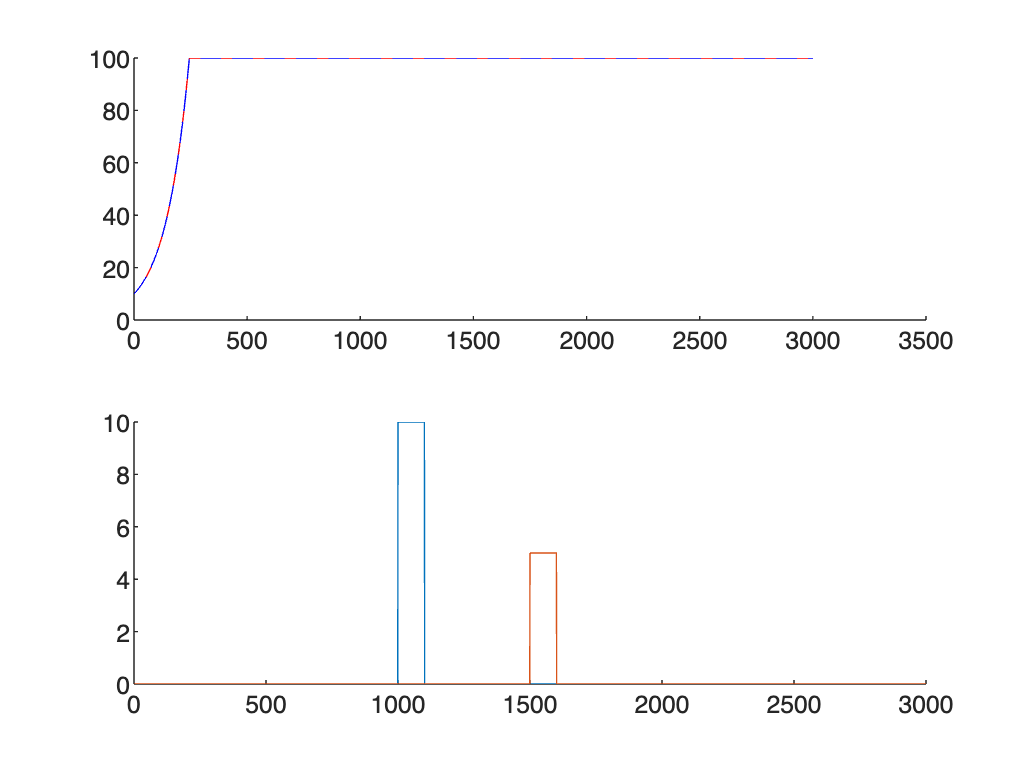

times = 1:1:3000;
weights = [1.1, -0.15;
          -0.15,  1.1];
inputs = [inputArray(1000,1100,10,times);inputArray(1500,1600,5,times)]';
  
a=1.2;

N = FireRate(times,a,weights,inputs);

figure;
subplot(1,2,1)
subplot(2,1,1); hold on;
plot(N(:,1),'r-')
plot(N(:,2),'b--')
subplot(2,1,2);hold on;
plot(inputs)

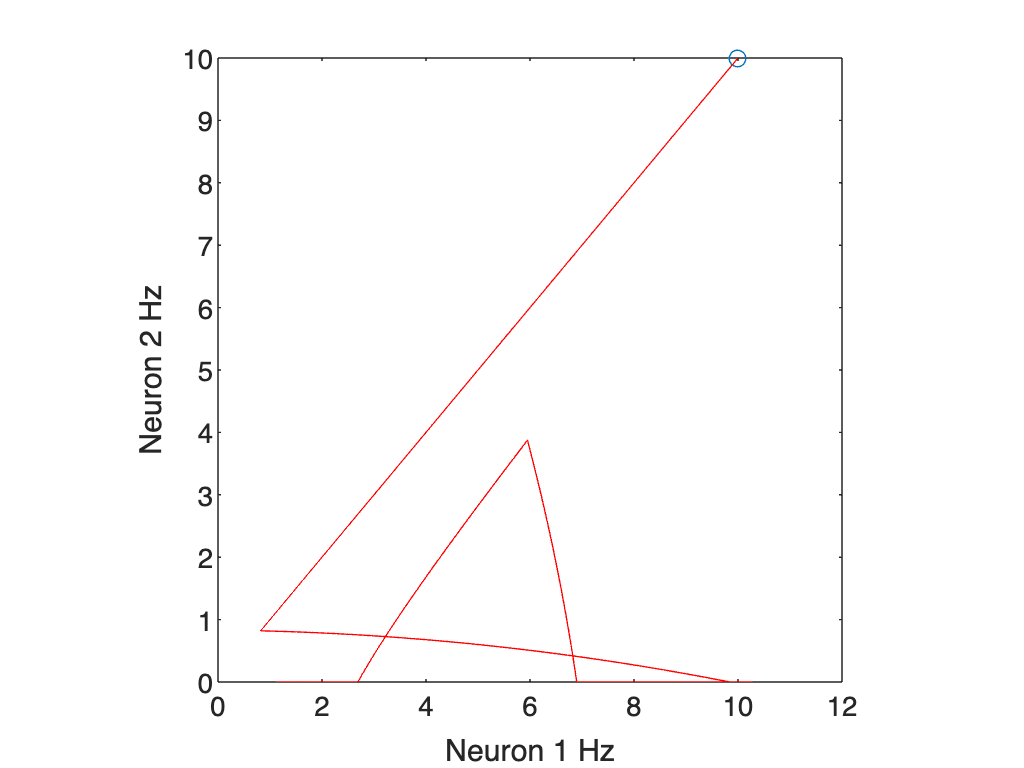


figure;
plot(N(1,1),N(1,2),'o'); hold on;
plot(N(:,1),N(:,2), 'r-');
xlabel('Neuron 1 Hz')
ylabel('Neuron 2 Hz')
axis('square')

Dynamics calculations

trace = -2*a+weights(1,1)+weights(2,2)

trace = -0.2000

det = (-a+weights(1,1))*(-a+weights(2,2))-weights(1,2)*weights(2,1)

det = -0.0125


trace^2>4*det

ans = logical
   1
